% Live notebook to demonstrate HW3.
clear all, close all, clc

% Q1. Add extra images and labels to dataset
addImages;
load faces_updated.mat;

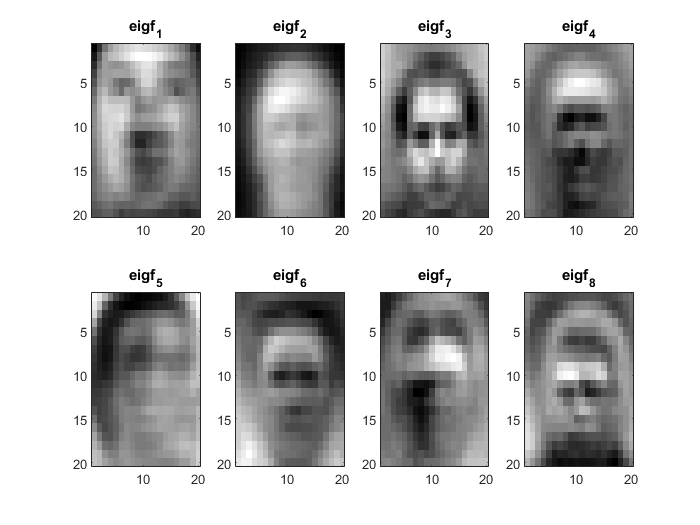

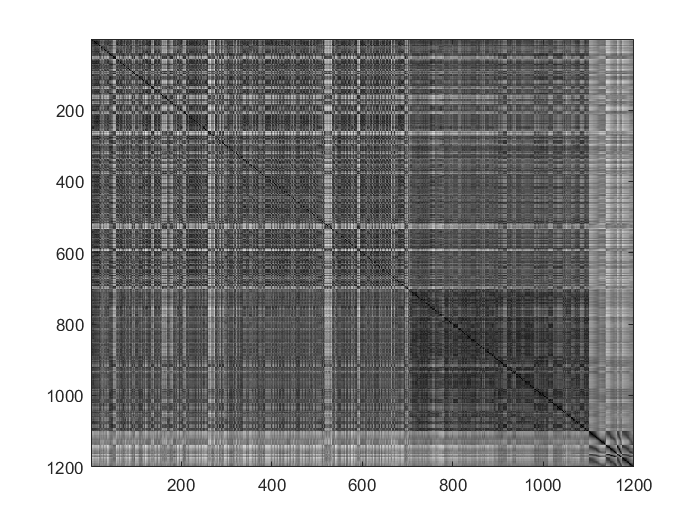

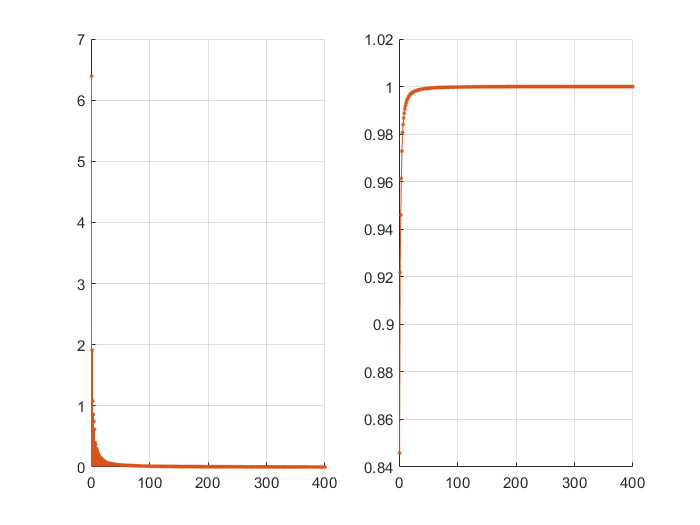

% Q2. getEigenfacemodel
show = 1;
d0 = 32;
Eigenmodel = getEigenfacemodel(faces, d0, show);

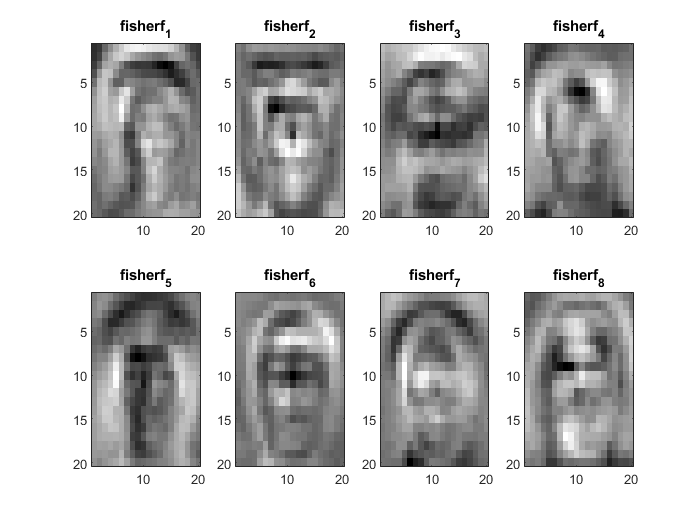

% Q3. getFisherfacemodel
d1 = 16;
getFisherfacemodel(faces, Eigenmodel, ids, d1, show);

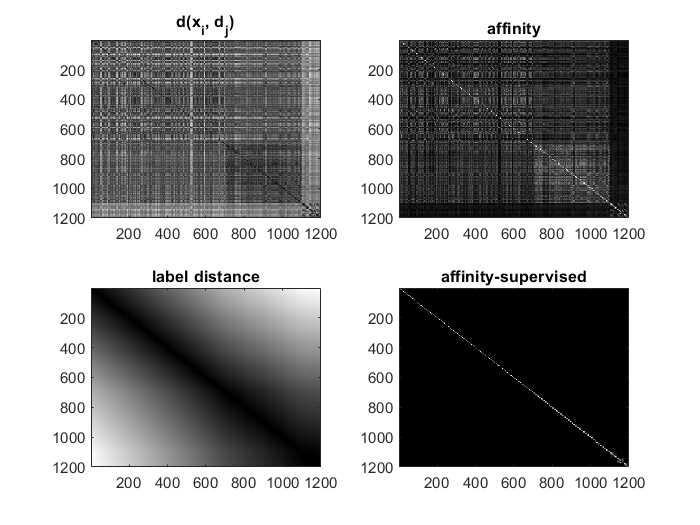

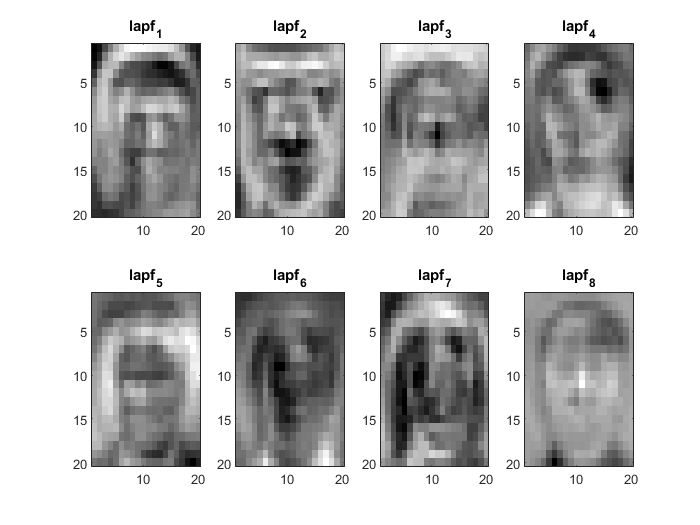

% Q4. getLaplacianfacemodel
d2 = 8;
getLaplcaianfacemodel(faces, Eigenmodel, ids, d2, show);

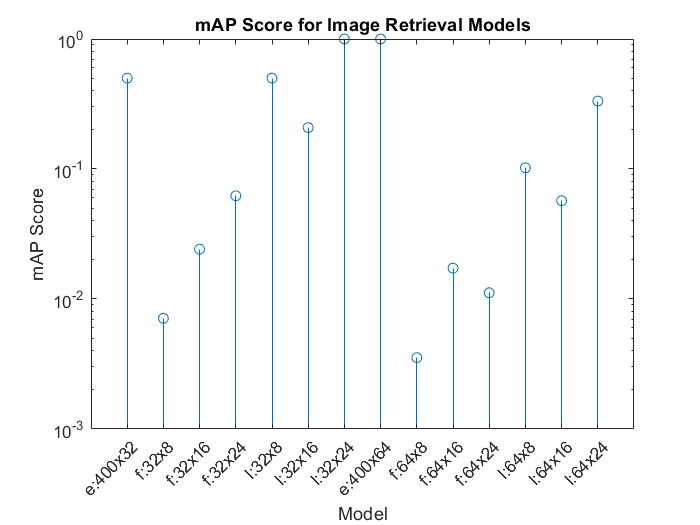


Guide: e - Eigenface. f - Fisherface. l - Laplacianface.

Model: e:400x32
Score: 0.5000

Model: f:32x8
Score: 0.0071

Model: f:32x16
Score: 0.0242

Model: f:32x24
Score: 0.0623

Model: l:32x8
Score: 0.5000

Model: l:32x16
Score: 0.2083

Model: l:32x24
Score: 1.0000

Model: e:400x64
Score: 1.0000

Model: f:64x8
Score: 0.0035

Model: f:64x16
Score: 0.0173

Model: f:64x24
Score: 0.0112

Model: l:64x8
Score: 0.1021

Model: l:64x16
Score: 0.0570

Model: l:64x24
Score: 0.3333



% Q5. The whole shebang. Running a retrieval query for all 14 possible
%     models, where d0 = [32, 43] for Eigenface models and d1/d2 = [8, 16, 24]
%     for Fisherface/Laplacianface models.

query_id = 999; % testing added image
main(query_id);